# File Name: Search_Registration_01_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Find Points Within a Cuboid ROI in Point Cloud

Read a point cloud data into the workspace.

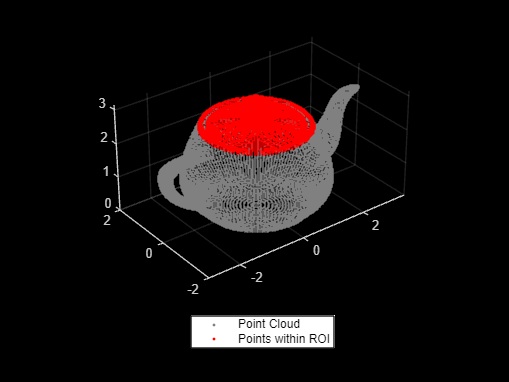

ptCloud = pcread('teapot.ply');

% Define a cuboid ROI within the range of the x, y and z coordinates of the input point cloud.
roi = [-2 2 -2 2 2.4 3.5];

%%%%%%%%%% TODO %%%%%%%%%%
% Find the indices of the points that lie within the cuboid ROI.
indices = findPointsInROI(ptCloud,roi);

% Select the points that lie within the cuboid ROI and store as a point cloud object.
ptCloudB = select(ptCloud,indices);

% Display the input point cloud and the point cloud within the specified ROI.
figure
pcshow(ptCloud.Location,[0.5 0.5 0.5])
hold on
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
hold off